# **UE1 USRP B210  Receiver **

## Set OFDM Frame Parameters

% Clear all the function data as they contain some persistent variables
clear;
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset getTrParamsforSpecificBS_id;
close all;
% 第一部分可以认为是控制基站的功能
% The chosen set of OFDM parameters overall for all BSs:
overAllOfdmParams.online_BS               = 2;              % number of online data BS 
overAllOfdmParams.FFTLength               = 256;              % FFT length
overAllOfdmParams.CPLength                = ceil(overAllOfdmParams.FFTLength*0.25);   % Cyclic prefix length
overAllOfdmParams.Subcarrierspacing       = 30e3;               % Sub-carrier spacing of 30 KHz
total_RB                                  = 17;                                % User input Resource block number

% 调用calculateRBFinal函数确保最终的RB确定的子载波总数能够被pilot subcarrier spacing整除
[RB_verified, MaxRB] = calculateRBFinal(overAllOfdmParams, total_RB);
% 补充，其实新的算法不需要这个强限制，直接传入total RB即可

% check if RB_verified exceed MaxRB
if total_RB > MaxRB || RB_verified > MaxRB
    error('Error: Defined RB (%d) exceeds the system maximum allowed RB (%d). ', RB_verified, MaxRB);
end

overAllOfdmParams.total_RB                     = total_RB;
overAllOfdmParams.total_NumSubcarriers         = overAllOfdmParams.total_RB*12;                  % Number of sub-carriers in the band = resourceblock * 12 (must less than FFTlength)
overAllOfdmParams.guard_interval = (overAllOfdmParams.FFTLength - overAllOfdmParams.total_NumSubcarriers) / 2;     % Guard interval, 单侧的空载波
% check if NumSubcarriers less than FFTLength
if overAllOfdmParams.total_NumSubcarriers > overAllOfdmParams.FFTLength
    error('Total NumSubcarriers: (%d) exceeds Total FFTLength: (%d), which is not allowed. Please reduce the value of RB.', ...
        overAllOfdmParams.total_NumSubcarriers, overAllOfdmParams.FFTLength);
end


## Initialize Receiver Parameters

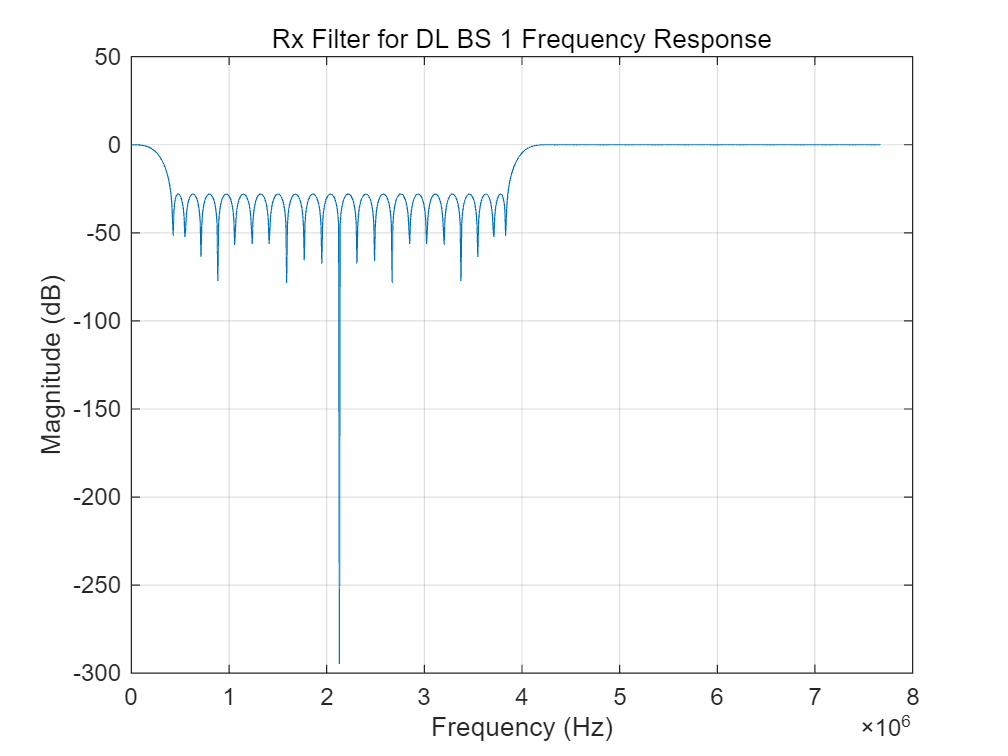

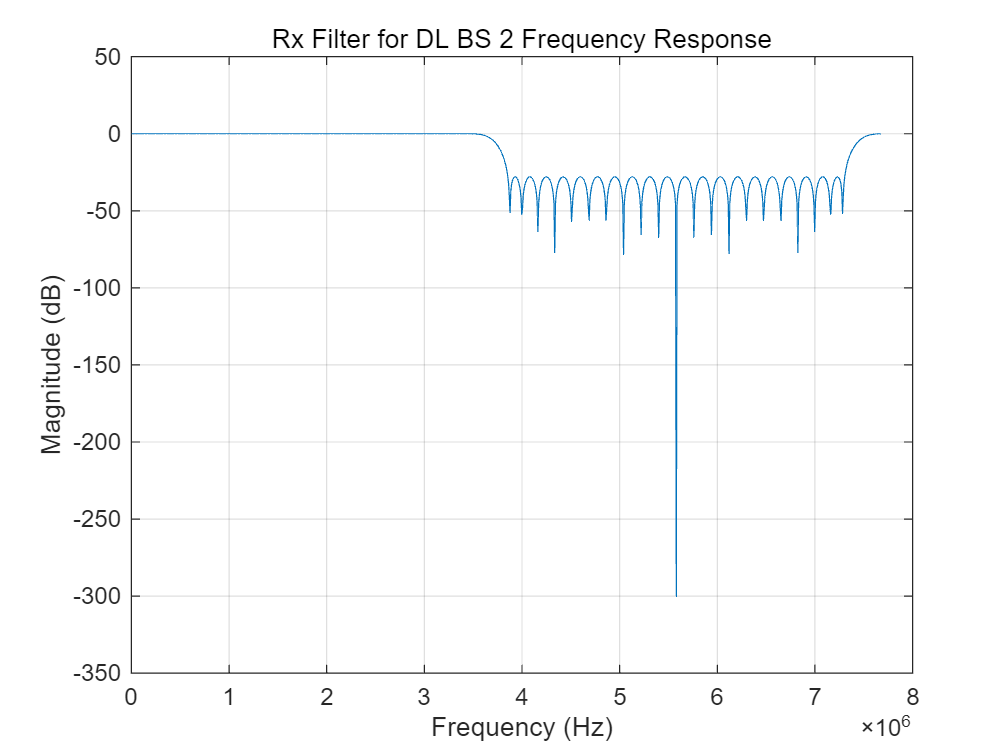

radioDevice            = "B210";   % Choose radio device for reception
channelmapping         = 1;  % mutichannel or single channel selection
centerFrequency        = 2.5e9;  % Center Frequency
centerFrequency        = 2.7e9;
gain                   = 60;  % Set radio gain
gain                   = 55;
save_data              = false;
watch_filteredResult   = false;
read_savedData         = true;
printoverflow          = true;

read_filename = 'saved_frameData_2BSTr_25664_5_6_5_6.bb';            % read saved received data from specific filename         
save_filename = 'saved_frameData_2BSTr_25664_2_3_5_6.bb';           % save receiving data to specific filename


% 接下来是针对UE B210联合分别接收不同基站数据的radio设置和具体接收算法流程+resource OFDM parameters
overAllOfdmParams.Rcv_DL_CoopBSs_id                   = [1,2];                %当前服务该用户的下行基站协作集, 接收BS id信号处理的顺序与list前后顺序一致
overAllOfdmParams.PilotSubcarrierSpacing              = [36,36];              % Pilot sub-carrier spacing
overAllOfdmParams.BWPoffset                           = [0,0];                %当前基站的总带宽offset（单位/1个子载波），offset设置的是实际带宽start位置相对于初始计算的start的位置的偏移
UE_id                                                 = 1;                    %当前UE的ID标识符
% 根据全局configure和特定配置，初始化所有接收下行基站的 sysParam、rxObj、OFDMParams、dataParams等参数保存至sysParamRxObj
sysParamRxObj = setupSysParamsAndRxObjects(overAllOfdmParams);

% 检查 sysParamRxObj 中所有基站的 field names和预先确定的overAllOfdmParams中协作基站集ID名称和顺序是否一致
BS_fieldnames = fieldnames(sysParamRxObj);
% 初始化接收机USRP radio和软接收object basbandreceiver bbr
radio = GetRxUsrpRadioObj(sysParamRxObj,radioDevice,centerFrequency,gain,channelmapping,read_savedData,read_filename);

Checking radio connections...


% 初始化所有基站的可视化工具
visualizationTools = setupVisualizationTools(sysParamRxObj);
% 初始化计算误码率对象
errorRate_collection = struct();  % 结构体保存每个基站的误码率对象
for index = 1:length(BS_fieldnames)
    % 为每个基站初始化误码率对象，并保存到 BER_objects 结构体中
    current_BS_field = BS_fieldnames{index};
    errorRate_collection.(current_BS_field) = comm.ErrorRate();
end

## Execute Receiver Loop

#### Synchronization

#### Frequency Offset Estimation and Correction

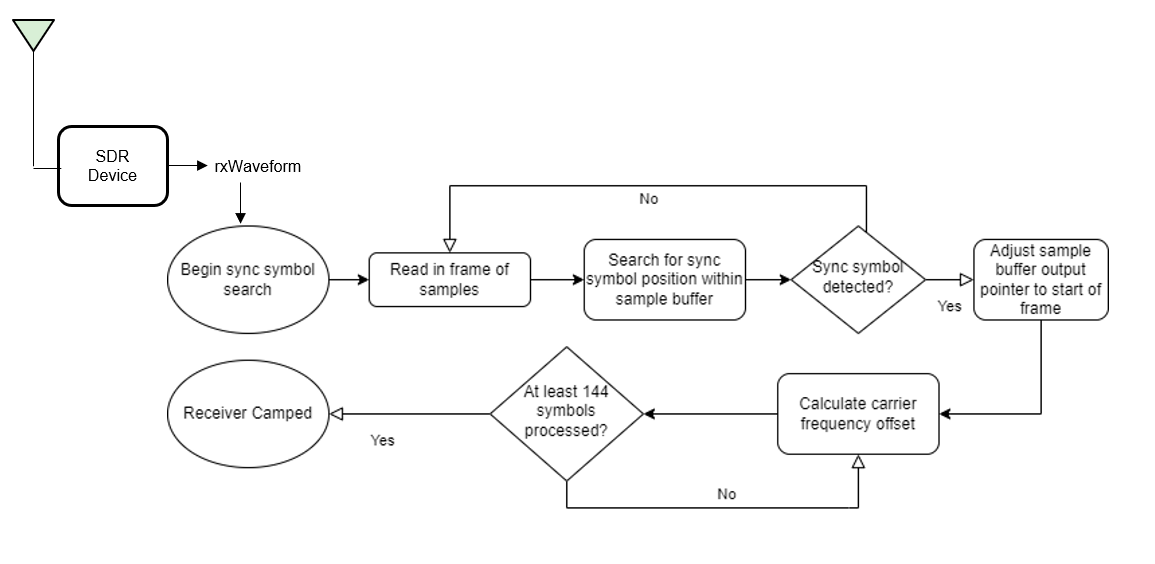

### Receiver Processing

#### Channel Estimation and Equalization

#### Header Decoding

#### Data Decoding

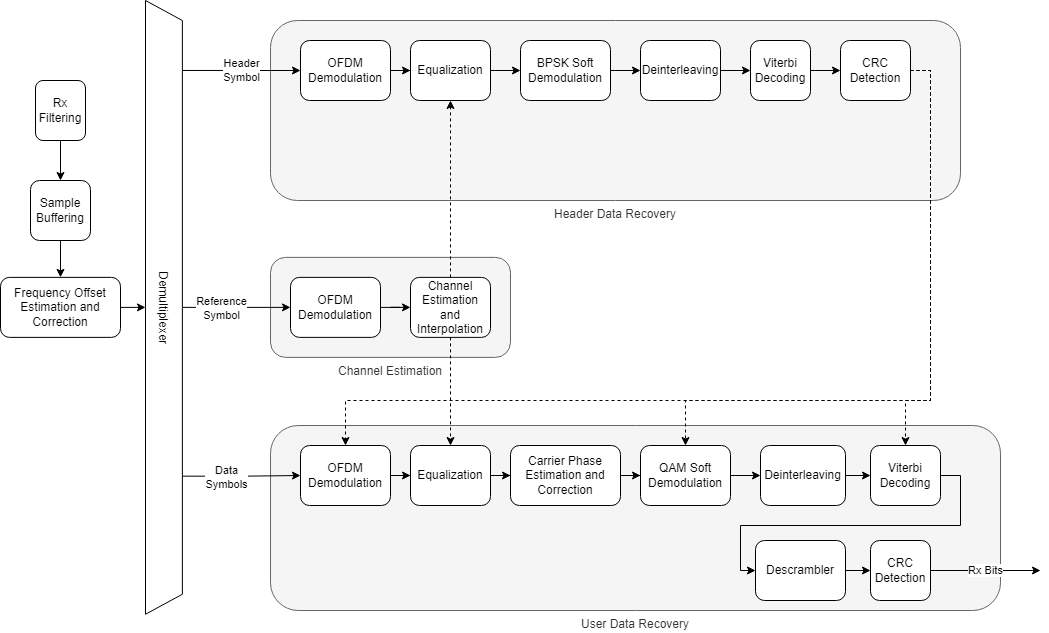

[DL_BS_1]Sync symbol found.
[DL_BS_1]Estimating carrier frequency offset ...
[DL_BS_2]Sync symbol found.
[DL_BS_2]Estimating carrier frequency offset ...
[DL_BS_1]Receiver camped.
[DL_BS_2]Receiver camped.
[DL_BS_1]Detected and processing frame 8
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.910126e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 8 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS

[DL_BS_2]Detected and processing frame 8
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.201804e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 8 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 9
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.909958e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 9 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS

[DL_BS_2]Detected and processing frame 9
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.202823e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 9 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 10
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.904906e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 10 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 10
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.201469e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 10 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 11
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.894959e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 11 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 11
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.195088e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 11 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 12
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.890095e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 12 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 12
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.193542e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 12 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 13
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.900197e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 13 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 13
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.193353e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 13 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 14
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.905529e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 14 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 14
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.194468e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 14 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 15
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.907323e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 15 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 15
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.192388e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 15 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 16
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.903914e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 16 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 16
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.188207e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 16 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 17
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.898257e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 17 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 17
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.189641e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 17 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 18
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.904877e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 18 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 18
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.192279e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 18 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 19
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.900397e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 19 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 19
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.197309e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 19 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 20
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.908019e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 20 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 20
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.193890e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 20 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 21
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.900971e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 21 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 21
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.191637e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 21 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 22
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.914132e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 22 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 22
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.189196e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 22 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 23
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.920979e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 23 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 23
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.189095e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 23 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 24
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.924778e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 24 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 24
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.186348e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 24 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 25
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.912315e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 25 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 25
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.187859e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 25 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 26
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.899059e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 26 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 26
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.190148e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 26 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 27
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.897741e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 27 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 27
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.190447e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 27 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 28
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.901867e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 28 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 28
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.189433e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 28 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 29
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.908858e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 29 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

[DL_BS_2]Detected and processing frame 29
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.187063e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 29 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

____________________________________________________________________________


[DL_BS_1]Detected and processing frame 30
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.901432e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 256QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_1]Received data in frame 30 from DL_BS_1: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from B

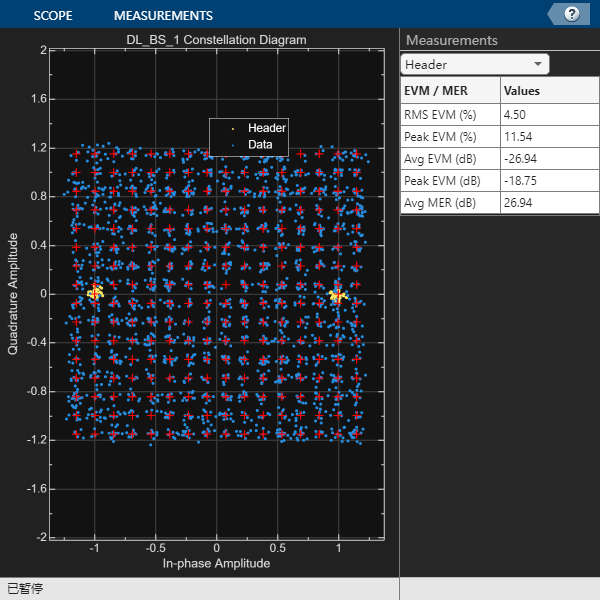

[DL_BS_2]Detected and processing frame 30
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -6.187136e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=5/6, and FFT Length=256
Data CRC passed
Data decoding completed
------------------------------------------


[DL_BS_2]Received data in frame 30 from DL_BS_2: BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test!BS2 N320 report! this is FD-RAN hardware prototype test

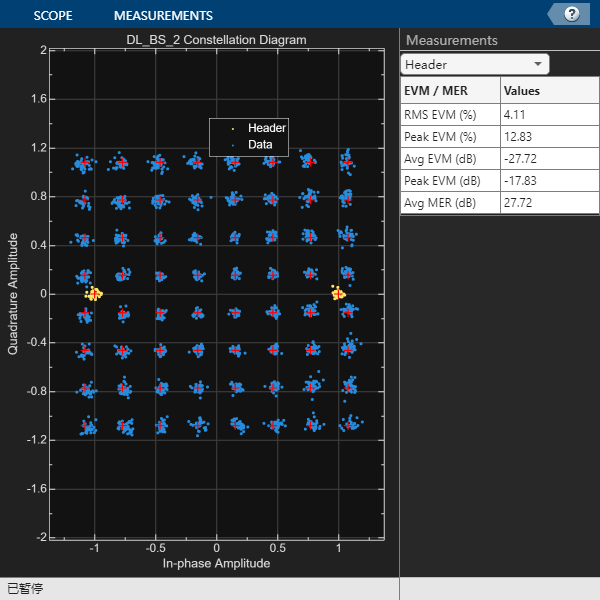

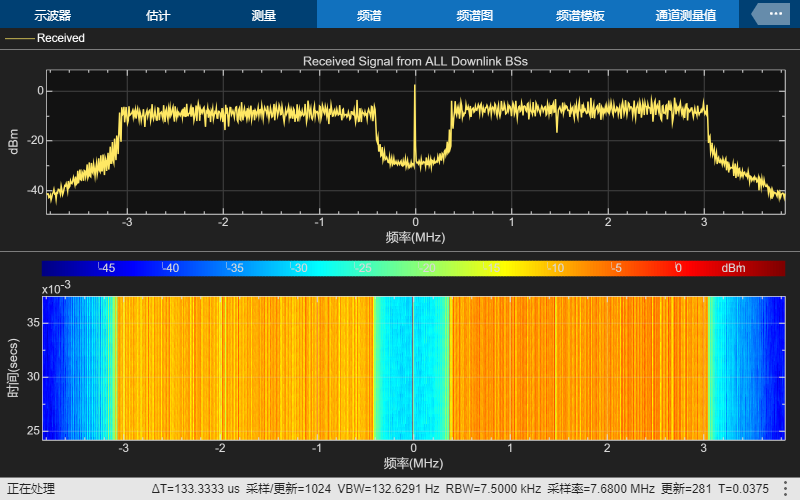

data_collec = [];
overflow = 0;
toverflow = 0;  % Receiver overflow count
BER_collection = struct();
EVM_collection = struct();
MER_collection = struct();
isConnected = false;
% 循环遍历每个帧
for frameNum = 1:30
    if read_savedData
        rxWaveform = radio();  % 读取保存的数据
    else
        [rxWaveform, ~, overflow] = radio();  % 从无线电设备中读取数据
    end

    if (overflow > 0) && printoverflow
        fprintf('Overflow occurred at frame number: %d\n', frameNum);
    end

    if save_data
        data_collec = [data_collec; rxWaveform];  % 保存接收的数据
    end
    toverflow = toverflow + overflow;

    % 如果没有 overflow，继续解调处理
    if ~overflow
        if isConnected
            fprintf('____________________________________________________________________________\n')
        end
        % 生成 rxWaveform 的多个副本，数量为基站数量
        numBSs = length(BS_fieldnames);
        rxWaveformCopies = cell(1, numBSs);
        for i = 1:numBSs
            rxWaveformCopies{i} = rxWaveform;  % 为每个基站生成副本
        end


        % 遍历协作基站集
        for index = 1:length(BS_fieldnames)
            % 获取对应基站的部分参数用于后续计算
            current_BS_field = BS_fieldnames{index};
            SampleRate=sysParamRxObj.(current_BS_field).sysParam.SampleRate;
            transportBlk_bs = sysParamRxObj.(current_BS_field).transportBlk_bs;

            % 初始化保存每个基站每帧BER的结构体
            if ~isfield(BER_collection, current_BS_field)
                BER_collection.(current_BS_field) = zeros(1, sysParamRxObj.(current_BS_field).dataParams.numFrames);
            end

            % 初始化保存 EVM 和 MER 的结构体
            if ~isfield(EVM_collection, current_BS_field)
                EVM_collection.(current_BS_field).header = zeros(1, sysParamRxObj.(current_BS_field).dataParams.numFrames);  % 30 帧
                EVM_collection.(current_BS_field).data = zeros(1, sysParamRxObj.(current_BS_field).dataParams.numFrames);
                MER_collection.(current_BS_field).header = zeros(1, sysParamRxObj.(current_BS_field).dataParams.numFrames);
                MER_collection.(current_BS_field).data = zeros(1, sysParamRxObj.(current_BS_field).dataParams.numFrames);
            end
            
            % 从副本中获取当前基站对应的 rxWaveform
            rxWaveform_for_currentBS = rxWaveformCopies{index};

            % 运行接收前端
            rxIn = helperOFDMRxFrontEnd(rxWaveform_for_currentBS, ...
                sysParamRxObj.(current_BS_field).sysParam, ...
                sysParamRxObj.(current_BS_field).rxObj, ...
                visualizationTools.(current_BS_field).spectrumAnalyze, ...
                watch_filteredResult);

            % 运行接收处理
            [rxDataBits, isConnected, toff, rxDiagnostics] = helperOFDMRx(rxIn, ...
                sysParamRxObj.(current_BS_field).sysParam, ...
                sysParamRxObj.(current_BS_field).rxObj, ...
                visualizationTools.(current_BS_field).timesink, frameNum);
            sysParamRxObj.(current_BS_field).sysParam.timingAdvance = toff;

            % 收集误码率和帧错误统计
            if isConnected
                % 更新误码率
                berVals_bs = errorRate_collection.(current_BS_field)(transportBlk_bs((1:sysParamRxObj.(current_BS_field).sysParam.trBlkSize)).', rxDataBits);
                BER_collection.(current_BS_field)(frameNum) = berVals_bs(1);

                if sysParamRxObj.(current_BS_field).dataParams.printData
                    % 打印接收到的数据
                    numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits), 7);
                    recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode), 7, []), 7));
                    fprintf('[%s]Received data in frame %d from %s: %s\n', current_BS_field, frameNum, current_BS_field, recData);
                end
            end

            % 计算 EVM 和 MER
            if isConnected && sysParamRxObj.(current_BS_field).dataParams.enableConst_measure
                % 计算并保存每帧的 EVM 和 MER
                EVM_collection.(current_BS_field).header(frameNum) = visualizationTools.(current_BS_field).constellation_measure.evm_header( ...
                    complex(rxDiagnostics.rxConstellationHeader(:)));
                EVM_collection.(current_BS_field).data(frameNum) = visualizationTools.(current_BS_field).constellation_measure.evm_data( ...
                    complex(rxDiagnostics.rxConstellationData(:)));
                MER_collection.(current_BS_field).header(frameNum) = visualizationTools.(current_BS_field).constellation_measure.mer_header( ...
                    complex(rxDiagnostics.rxConstellationHeader(:)));
                MER_collection.(current_BS_field).data(frameNum) = visualizationTools.(current_BS_field).constellation_measure.mer_data( ...
                    complex(rxDiagnostics.rxConstellationData(:)));
            end

            % 显示星座图和测量信息
            if isConnected && sysParamRxObj.(current_BS_field).dataParams.enableScopes
                visualizationTools.(current_BS_field).constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), complex(rxDiagnostics.rxConstellationData(:)));
            end  
        end
        % 显示频谱分析
        if sysParamRxObj.(current_BS_field).dataParams.enableScopes && ~watch_filteredResult
            visualizationTools.(current_BS_field).spectrumAnalyze.Title = 'Received Signal from ALL Downlink BSs';
            visualizationTools.(current_BS_field).spectrumAnalyze(rxWaveform);
        end
    end
end


fprintf(['----------------------------\n' ...
    'Simulation complete!\n' ...
    'Total number of overflow: %d\n' ...);
    '----------------------------\n'], toverflow)

----------------------------
Simulation complete!
Total number of overflow: 0
----------------------------


% 显示每个基站的平均 BER 值和 EVM、MER 测量结果
for index = 1:length(BS_fieldnames)
    current_BS_field = BS_fieldnames{index};
    % 平均 BER
    avg_BER = mean(BER_collection.(current_BS_field));
    fprintf('-------measurement-------\n')
    fprintf('%s Measurement:\n', current_BS_field);
    fprintf('%s Average BER = %.4e\n', current_BS_field, avg_BER);

    % 平均 EVM 和 MER
    avg_EVM_header = mean(EVM_collection.(current_BS_field).header);
    avg_EVM_data = mean(EVM_collection.(current_BS_field).data);
    avg_MER_header = mean(MER_collection.(current_BS_field).header);
    avg_MER_data = mean(MER_collection.(current_BS_field).data);

    fprintf('Header rms EVM(%%): %.3f %%\n', avg_EVM_header);
    fprintf('Data rms EVM(%%): %.3f %%\n', avg_EVM_data);
    fprintf('Header MER(dB): %.3f dB\n', avg_MER_header);
    fprintf('Data MER(dB): %.3f dB\n \n', avg_MER_data);
end

-------measurement-------


DL_BS_1 Measurement:


DL_BS_1 Average BER = 0.0000e+00


Header rms EVM(%): 3.507 %


Data rms EVM(%): 3.372 %


Header MER(dB): 20.546 dB


Data MER(dB): 20.804 dB
 


-------measurement-------


DL_BS_2 Measurement:


DL_BS_2 Average BER = 0.0000e+00


Header rms EVM(%): 3.131 %


Data rms EVM(%): 3.234 %


Header MER(dB): 21.304 dB


Data MER(dB): 21.085 dB
 



% 保存数据
if save_data
    bbw = comm.BasebandFileWriter(save_filename, SampleRate=SampleRate, CenterFrequency=centerFrequency);
    bbw(data_collec);
    info(bbw);
    release(bbw);
end

% 释放资源
release(radio);
